%Model comparison for ternary TOJ in the pre/post test

clear all; close all; clc;

subjIDs = 3:9;
nsub = length(subjIDs);
deltaAIC = NaN(nsub,5); % number of subjects x number of models
s_estP = cell(1, nsub);
for i = 1:nsub
    subjID = subjIDs(i);
    [deltaAIC(subjID,:) s_estP{subjID}] = model_comp_fitting_v2(subjID);
end
disp('fitting done!')

fitting done!


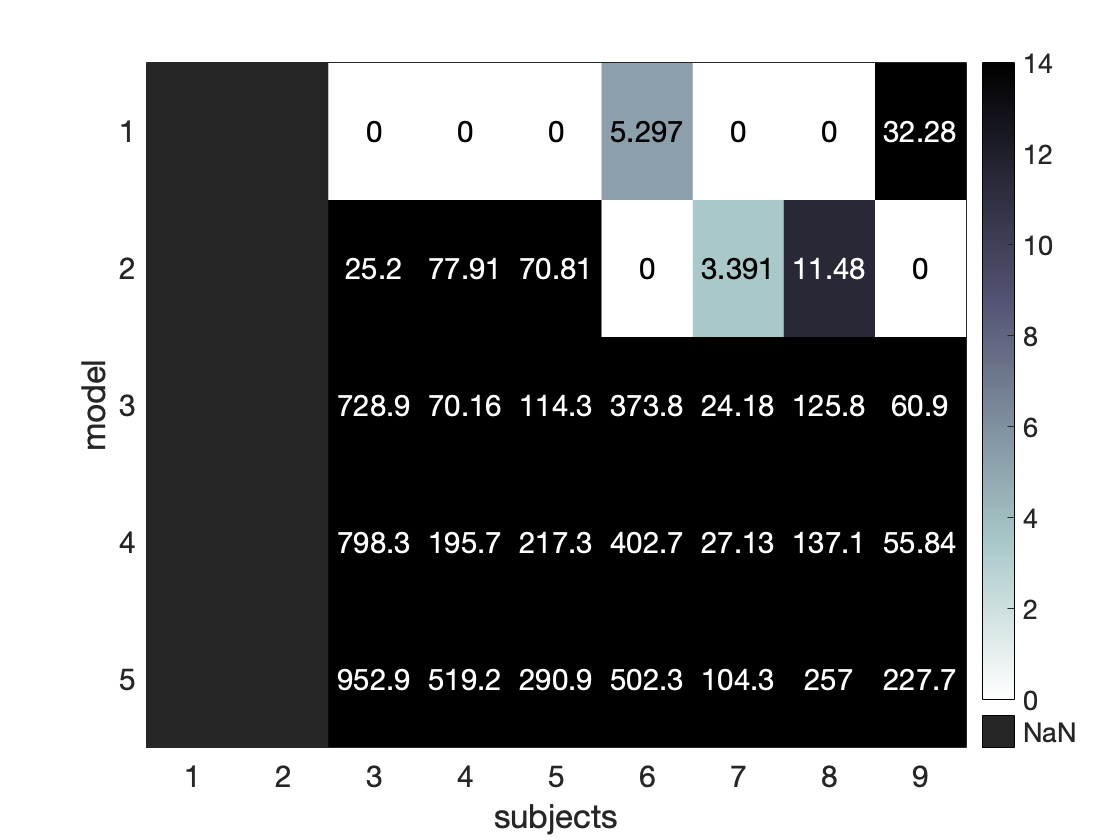

%% plotting summary table
figure
heatmap(deltaAIC', 'XLabel','subjects', 'Colormap', flipud(bone),...
    'ColorLimits', [0, 14], 'ColorbarVisible', 'off', 'GridVisible', 'off',...
    'FontSize', 15, 'YLabel', 'model'); colorbar

%% plotting curve fitting with the best-fitting parameters
for i = 1:nsub
    subjID = subjIDs(i);
    for sess = 1:9
        bestModel = 1;
        bestP = s_estP{subjID}{sess, bestModel};
        model_comp_plotting_v2(subjID, sess, bestModel, bestP)
    end
end

     1



     2



     3



     4



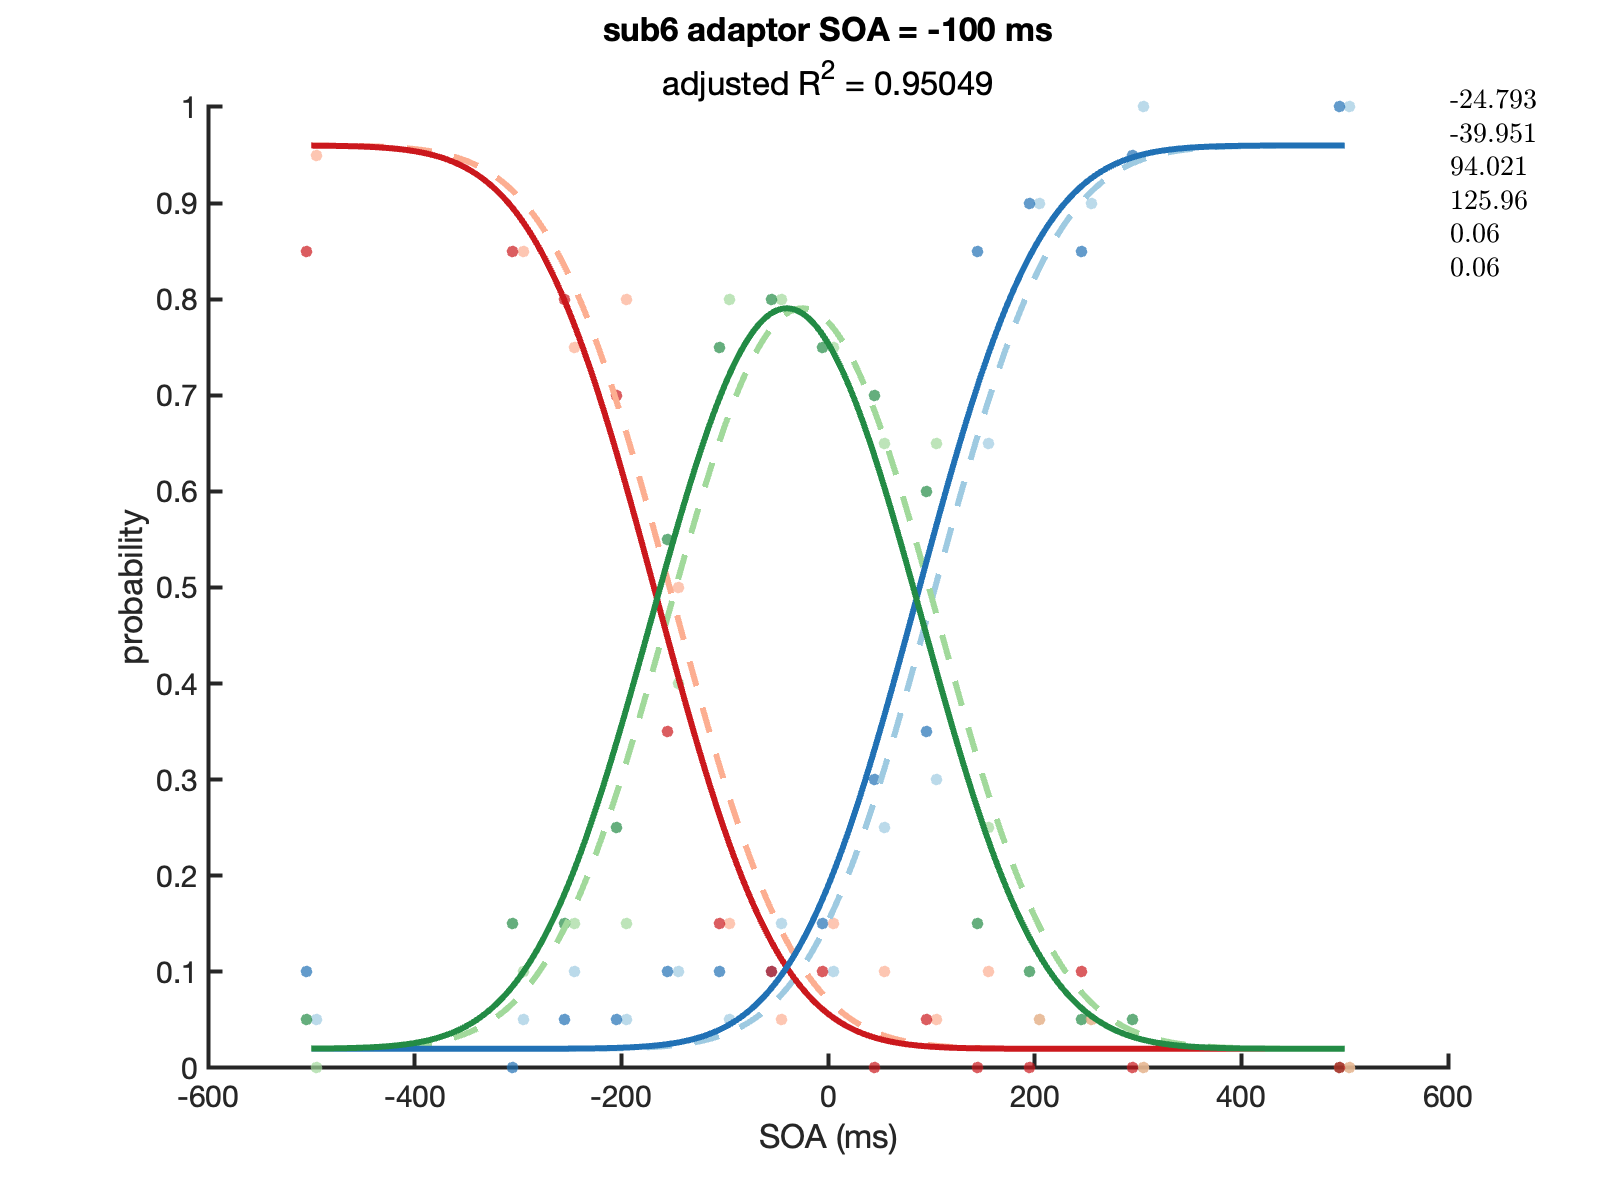

     5



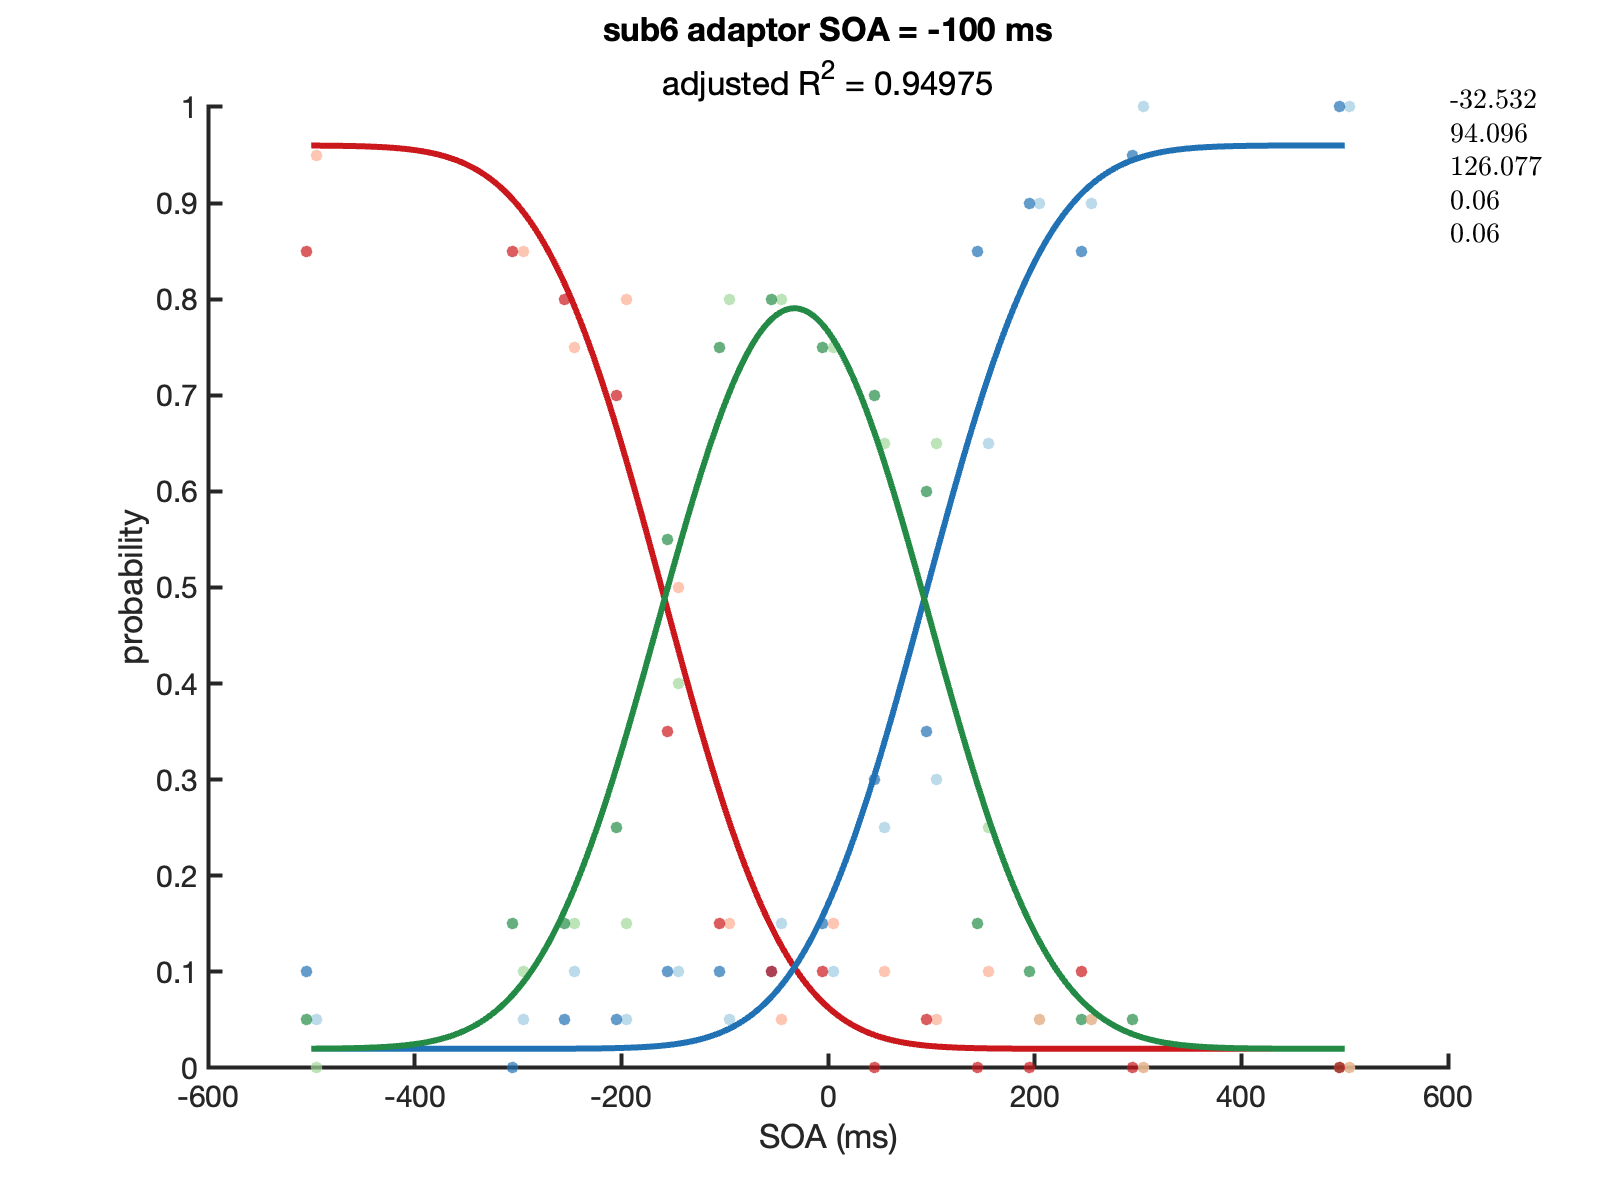

%% Plot one single session with different models

subjID = 6;
sess = 1;
for bestModel = 1:5
    disp(bestModel)
    bestP = s_estP{subjID}{sess, bestModel};
    model_comp_plotting_v2(subjID, sess, bestModel, bestP)
end

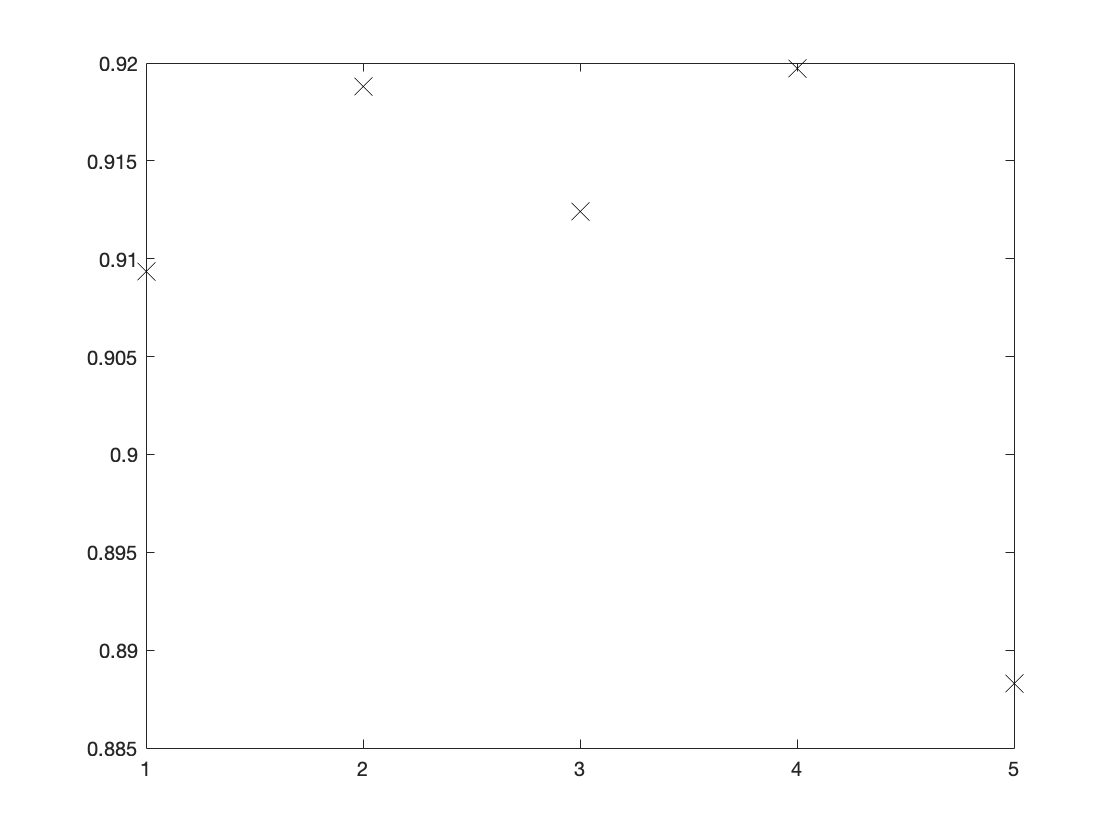

%% test goodness of fit

subjID = 8;
sess = 1;
for bestModel = 1:5
    bestP = s_estP{subjID}{sess, bestModel};
    [R2(bestModel), aR2(bestModel)] = model_comp_gof_v2(subjID, sess, bestModel, bestP);
end
figure;plot([1:5],R2,'kx','MarkerSize',10)
xticks([0:6])